BackTestV2

clear
tic

T = readtable("Trend Trading Input Output Data.xlsx", "Sheet","Price Data");

PriceTTraw = table2timetable (T) ;

PriceTTSemiClean = fillmissing (PriceTTraw, "previous") ;
PriceTT = fillmissing (PriceTTSemiClean, "next") ;

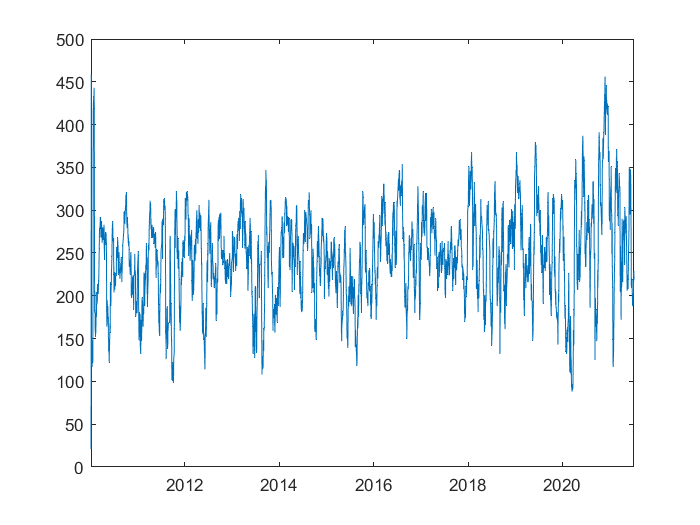

%SMA Signal
LeadDays = 1 ; 
LagDays = 20 ;

SMALead = movavg (PriceTT, 'simple', LeadDays) ;
SMALag = movavg (PriceTT, 'simple', LagDays) ;

SMASignalTT = PriceTT ;
SMASignalTT.Variables = SMALead.Variables > 1 * SMALag.Variables ;
SMASignalFinalTT = SMASignalTT ;
SMASignalFinal = SMASignalFinalTT.Variables ;
% SMASignal = SMASignalTT.Variables ;
% SMASignalFinal (2:end, :) = SMASignal (1:end-1, :) ;
% SMASignalFinal (1, :) = 0 ;
% SMASignalFinalTT.Variables = SMASignalFinal

nDailySignal = sum(SMASignalFinal,2) ;
nDailySignalTT = timetable (SMASignalFinalTT.Time, nDailySignal, 'VariableNames',"nDailySignal") ;
plot (nDailySignalTT.Time, nDailySignalTT.Variables )


%Strategy
TradingCosts = [0.2/100, 0.2/100] ;

SMAInitWeights = ComputeWeights (SMASignalFinalTT (LagDays, :)) ;
SMArebalanceFcn = @(w,p,s) CrossoverRebalanceFcn (w,p,s) ;
SMAStrategy = backtestStrategy ('SMAStrategyBacktest', SMArebalanceFcn, ...
    'TransactionCosts',TradingCosts, "RebalanceFrequency", 1, ...
    "LookbackWindow", 2, "InitialWeights",SMAInitWeights ) 

SMAStrategy =   backtestStrategy with properties:

                  Name: "SMAStrategyBacktest"
          RebalanceFcn: @(w,s)CrossoverRebalanceFcn(w,s)
    RebalanceFrequency: 1
      TransactionCosts: [0.0020 0.0020]
        LookbackWindow: 2
        InitialWeights: [1×665 double]



%Set-up backtest engine
bt = backtestEngine(SMAStrategy, 'RiskFreeRate', 0.0/365, ...
    "InitialPortfolioValue", 10^9)

bt =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
    InitialPortfolioValue: 1.0000e+09
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []



% run the strategy backtest
startIdx = max(LeadDays, LagDays) ;

bt = runBacktest (bt, PriceTT, SMASignalFinalTT, 'start', startIdx) 

bt =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
    InitialPortfolioValue: 1.0000e+09
                NumAssets: 665
                  Returns: [2839×1 timetable]
                Positions: [1×1 struct]
                 Turnover: [2839×1 timetable]
                  BuyCost: [2839×1 timetable]
                 SellCost: [2839×1 timetable]


% Summary
SummaryTable = summary (bt)

SummaryTable = 9×1 table
                       SMAStrategyBacktest
                       ___________________

    TotalReturn                2.4172     
    SharpeRatio              0.058562     
    Volatility              0.0079233     
    AverageTurnover                 0     
    MaxTurnover                     0     
    AverageReturn          0.00046392     
    MaxDrawdown               0.29631     
    AverageBuyCost                  0     
    AverageSellCost                 0     


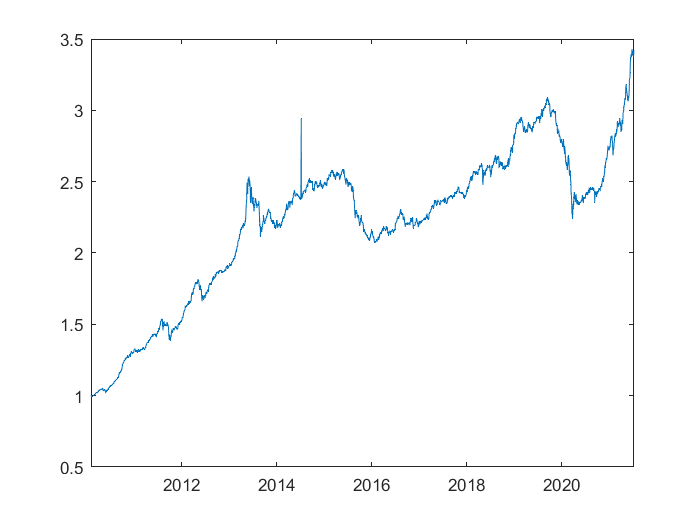

%Plot cumulative return
dailyRet = bt.Returns ;
portfolioValue = ret2tick (dailyRet) ;
plot (portfolioValue.Time, portfolioValue.Variables)


%Asset area plot
time = bt.Positions.SMAStrategyBacktest.Time ;
positions = bt.Positions.SMAStrategyBacktest.Variables ;

Period = yearfrac (time(1), time(end))

Period = 11.4493

PortValue = portfolioValue.Variables ;
portfolioValue (end,:)

ans = 1×1 timetable
       Time        SMAStrategyBacktest
    ___________    ___________________

    09-Jul-2021          3.4172       


CAGR = (PortValue (end))^(1/Period)-1

CAGR = 0.1133


PositionsTT = bt.Positions.SMAStrategyBacktest ;
InitialWeightsTT = bt.Strategies.InitialWeights ;

outputFilename = 'Output.xlsx' ;
writetimetable (PositionsTT, outputFilename, 'sheet', "PositionsTT") ;
writematrix (InitialWeightsTT , outputFilename, 'sheet', "InitialWeightsTT") ;


% h = area (time, positions)

% assetAreaPlot (bt, 'SMAStrategyBacktest')

toc

Elapsed time is 144.057512 seconds.


Local functions

function CapAlloc = ComputeWeights (SignalTT) 
% Compute weights based on most recent signal.

Signals = SignalTT.Variables ;
nInvestableAssets = sum (Signals(end, :), 2) ;

CapAlloc = Signals(end, :)/nInvestableAssets ;
CapAlloc (isinf (CapAlloc)) = 0 ;

end

function new_weights = RebalanceWeightsFcn (Current_Weights, SignalTT) 
% Compute weights based on most recent signal.

% Pull out the signal
CrossoverSignal = SignalTT.Variables ;

% Start with current weights
new_weights = Current_Weights ;

% Sell existing long positions where the signal has turned from 1 to 0
idx = CrossoverSignal(end,:) == 0 ;
new_weights (idx) = 0 ;

% Find new crossover (signal has turned from 0 to 1)
idx = CrossoverSignal (end,:) == 1 ;

% Bet sizing
AvailableCapital = 1 ;
UninvestedAssets = sum (CrossoverSignal(end, :)) ;
new_weights (idx) = AvailableCapital / UninvestedAssets ;


end

function InitialWeights = ComputeInitialWeights (SignalTT) 
% Compute initial weights based on most recent signal.

Signals = SignalTT.Variables ;
nAssets = size (Signals, 2) ;
FinalSignal = Signals (end, :) ;
buys = FinalSignal == 1 ;
InitialWeights = zeros (1, nAssets) ;
InitialWeights (buys) = 1/nAssets ;

end


function new_weights = CrossoverRebalanceFcn (Current_Weights, PriceTT,SignalTT) 
% Signal crossover rebalance function.

% Pull out the signal
CrossoverSignal = SignalTT.Variables ;

% Start with current weights
new_weights = Current_Weights ;

% Sell existing long positions where the signal has turned from 1 to 0
idx = CrossoverSignal(end,:) == 0 ;
new_weights (idx) = 0 ;

% Find new crossover (signal has turned from 0 to 1)
idx = and (CrossoverSignal (end-1,:) == 0, CrossoverSignal (end,:) == 1 ) ;

% Bet sizing
AvailableCapital = 1 - sum (new_weights) ;
UninvestedAssets = 1 - sum (new_weights == 0) ;
new_weights (idx) = AvailableCapital / UninvestedAssets ;

end


function assetAreaPlot(backtester,strategyName)
% Plot the asset allocation as an area plot.

t = backtester.Positions.(strategyName).Time;
positions = backtester.Positions.(strategyName).Variables;
h = area(t,positions);
title(sprintf('%s Positions',strrep(strategyName,'_',' ')));
xlabel('Date');
ylabel('Asset Positions');
datetick('x','mm/dd','keepticks');
xlim([t(1) t(end)])
oldylim = ylim;
ylim([0 oldylim(2)]);
cm = parula(numel(h));
for i = 1:numel(h)
    set(h(i),'FaceColor',cm(i,:));
end
legend(backtester.Positions.(strategyName).Properties.VariableNames)

end